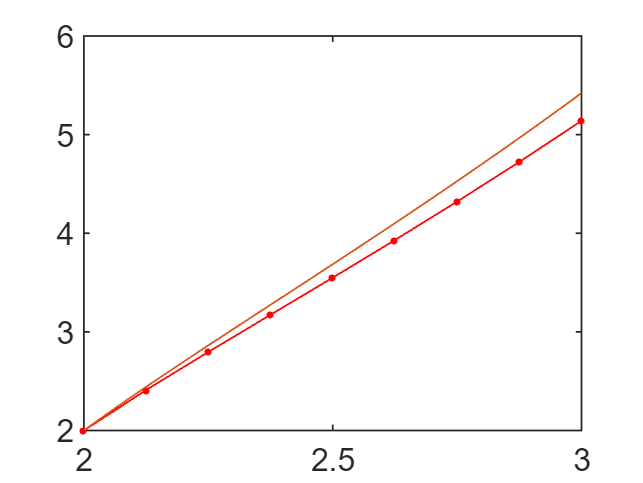

h = 1 / 3;
a = 2;
b = 3;

n = (b - a) / h;
t = linspace(a, b, n);
y0 = 2;

y = zeros([1, n]);
y(1) = y0;

for i = 1:n - 1
    y(i + 1) = y(i) + h * (exp(t(i)) / y(i));
end

figure
plot(t, y, '.r-')
hold on
fplot(@(t) sqrt(2) * sqrt(2 - exp(2) + exp(t)), [a, b])